First, we input the ODE

global C2 D2 U2 N2 Alph
C2 = 0.8; %infectiousness
D2 = 5 ;%infectious period
U2 = 0.1; %vacc. rate
N2 = 100000; %total pop
Alph = 5; %time until loss of immunity

gamma2 = C2*D2;
mu2 = U2*D2;
delt = D2/Alph;

y2 = [0, 0, 0];

S0 = 1.00; %recall that this has been non-dimensionalized, so we work in ratios.
I0 = 0.00; %start with 1% of pop infected
R0 = 0;
conditions = [S0; I0; R0];                                
span = [0 10];

[t2, y2] = ode45(@(t2,y2) odefun(t2, y2, gamma2 , mu2, delt), span, conditions);



Plot it

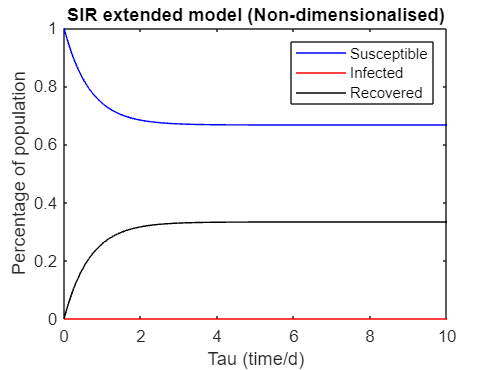

plot(t2, y2(:, 1), 'b', t2, y2(:, 2), "r", t2, y2(:, 3), "k")
title("SIR extended model (Non-dimensionalised)")
xlabel("Tau (time/d)")
ylabel("Percentage of population")
legend(["Susceptible", "Infected", "Recovered"])

Re-dimensionalise it

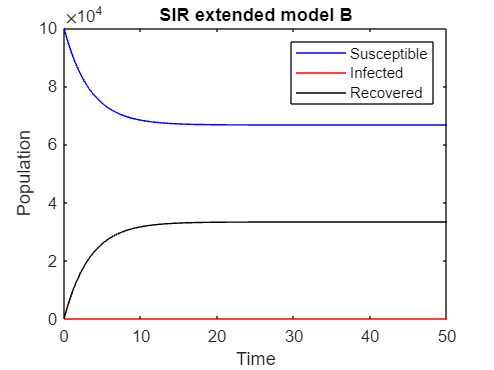

y2dim = y2*N2 ;
t2dim = t2*D2;
plot(t2dim, y2dim(:, 1), 'b', t2dim, y2dim(:, 2), "r", t2dim, y2dim(:, 3), "k")
title("SIR extended model B")
xlabel("Time")
ylabel("Population")
legend(["Susceptible", "Infected", "Recovered"])

Max_I2 = t2dim(find(y2dim(:, 2) == max(y2dim(:, 2))))

Max_I2 =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0045
    0.0070
    0.0095
    0.0121
    0.0246


Functions

function dydt = odefun(t2,y2, gamma2, mu2, delt)
dydt = zeros(3,1);
dydt(1) = -gamma2*y2(1)*y2(2) -mu2*y2(1)+delt*y2(3);
dydt(2) = gamma2*y2(1)*y2(2) -y2(2);
dydt(3) = y2(2) + mu2*y2(1)-delt*y2(3);
end